%正面同定実験の処理用スクリプト
clear, clc, close all
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2);% インポート用のセル
% MusicTime	PlayerRotY (deg)	Target (deg)	Accuracy (deg) 	SpentTime	MusicVol	VibVol

for i = 1:numFiles
% for i = 1:1
    %     Mx{i,1} = readmatrix(list(i).name);
    Mx{i,1} = readtable(list(i).name,'PreserveVariableNames',true);
    Mx{i,2} = rmmissing(Mx{i,1}); % 回答行だけ抽出（文字列が入った行を無視）
    Mx{i,3} = mean(Mx{i,2}{:,4}); % dotMean
    Mx{i,4} = rad2deg(acos(Mx{i,3})); %dotから角度に変換
    Mx{i,5} = rad2deg( std(Mx{i,2}{:,4})); % radStd
    Mx{i,6} = mean(Mx{i,2}{:,5}); % timeMean
    Mx{i,7} = std(Mx{i,2}{:,5}); % timeStd
    Mx{i,8} = Mx{i,2}{1,10}; % musicId
    Mx{i,9} = i; % musicId
end

% 行末に説明を追加
Mx{i+1,1} = '生データ';
Mx{i+1,2} = '回答抽出';
Mx{i+1,3} = 'dotMean';
Mx{i+1,4} = 'degMean';
Mx{i+1,5} = 'degStd';
Mx{i+1,6} = 'timeMean';
Mx{i+1,7} = 'timeStd';
Mx{i+1,8} = 'musicId';
Mx{i+1,9} = 'subjId';
save;


保存先:C:\Dropbox\論文\2稿目_音楽振動ナビ\V2実験データ\exp2_FrontDetect\matlab.mat




SortCell = Mx;
SortCell(i+1,:) = [];
Mz = sortrows(SortCell,8);
Mz{6,2}(20:21,:)=[];
Mz{20,2}(2,:)=[];


## 箱ひげ図描画

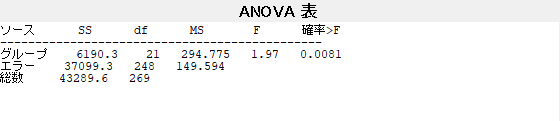

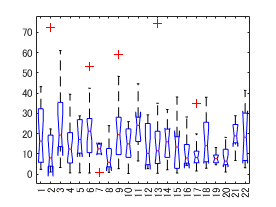

p = 0.0081

tbl = 4×6 の cell 配列
    {'ソース'  }    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'確率>F'  }
    {'グループ'}    {[6.1903e+03]}    {[ 21]}    {[294.7754]}    {[  1.9705]}    {[  0.0081]}
    {'エラー'  }    {[3.7099e+04]}    {[248]}    {[149.5941]}    {0×0 double}    {0×0 double}
    {'総数'   }    {[4.3290e+04]}    {[269]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = フィールドをもつ struct :
    gnames: {22×1 cell}
         n: [15 7 11 22 9 25 6 11 16 16 8 16 15 10 9 8 10 12 13 16 7 8]
    source: 'anova1'
     means: [19.6981 17.3790 26.0151 15.6264 17.6766 20.8427 11.0072 8.4918 21.1955 14.9817 23.4734 14.2621 16.4240 16.3269 12.6706 11.0755 10.8826 15.7200 7.9365 8.1959 19.1799 19.3501]
        df: 248
         s: 12.2309


% [Mx{1,2}{:,4}];
accuracy = 0;
accuracy_A = 0;
accuracy_B = 0;
time = 0;
time_A = 0;
time_B = 0;
grp = 0;
grp_A = 0;
grp_B = 0;

% for i = 1:size(Mx,1)-2
% 音楽順に並び替えたいとき
Data = Mz; 
for i = 1:size(Data,1)
    accuracy = horzcat(accuracy, transpose([Data{i,2}{:,4}]));
    time = horzcat(time, transpose([Data{i,2}{:,5}]));
    grp = horzcat(grp, i*ones(1,size(Data{i,2},1)));
    % music の種類で場合分け
    if Data{i,8} == 1
        accuracy_A  = horzcat(accuracy_A, transpose([Data{i,2}{:,4}]));
        time_A = horzcat(time_A, transpose([Data{i,2}{:,5}]));
        grp_A = horzcat(grp_A, i*ones(1,size(Data{i,2},1)));
    elseif Data{i,8} == 2
        accuracy_B  = horzcat(accuracy_B, transpose([Data{i,2}{:,4}]));
        time_B = horzcat(time_B, transpose([Data{i,2}{:,5}]));
        grp_B = horzcat(grp_B, i*ones(1,size(Data{i,2},1)));
    end
end
accuracy(:,1) = []; accuracy_A(:,1)=[]; accuracy_B(:,1)=[];
time(:,1) =[]; time_A(:,1) =[]; time_B(:,1) =[];
grp(:,1) =[]; grp_A(:,1) =[]; grp_B(:,1) =[];
accuracy = rad2deg(acos(accuracy));
accuracy_A = rad2deg(acos(accuracy_A));
accuracy_B = rad2deg(acos(accuracy_B));

% 参加者間でanova。P<0.05なら違いがある、すなわち全試行NG
[p,tbl,stats] = anova1(accuracy,grp)

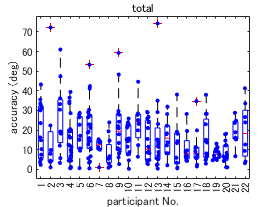

[p,tbl,stats] = anova1(time,grp)

figure;
boxplot(accuracy,grp);
hold on
swarmchart(grp,accuracy,[],'blue','filled','SizeData',10);
ylabel('accuracy (deg)')
xlabel('participant No.')
title('total')
hold off

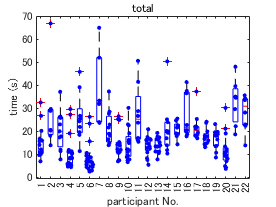


figure;
boxplot(time,grp);
hold on
swarmchart(grp,time,[],'blue','filled','SizeData',10);
ylabel('time (s)')
xlabel('participant No.')
title('total')
hold off



% 平均の計算
accu_total = mean([Mz{:,4}])

accu_total = 20.5725

std_total = std([Mz{:,4}])

std_total = 6.8998

accu_A = mean([Mz{1:11,4}])

accu_A = 22.5588

std_A = std([Mz{1:11,4}])

std_A = 7.6512

accu_B = mean([Mz{12:22,4}])

accu_B = 18.5861

std_B = std([Mz{12:22,4}])

std_B = 5.7230


[p,h,stats] = ranksum([Mz{1:11,4}],[Mz{12:22,4}])

p = 0.2122

h = logical
   0


stats = フィールドをもつ struct :
       zval: 1.2476
    ranksum: 146




time_total = mean([Mz{:,6}])

time_total = 20.4793

std_total = std([Mz{:,6}])

std_total = 7.7046


time_A = mean([Mz{1:11,6}])

time_A = 20.3820

std_A = std([Mz{1:11,6}])

std_A = 9.0874

time_B = mean([Mz{12:22,6}])

time_B = 20.5766

std_B = std([Mz{12:22,6}])

std_B = 6.4852

[p,h,stats] = ranksum([Mz{1:11,6}],[Mz{12:22,6}])

p = 0.9476

h = logical
   0


stats = フィールドをもつ struct :
       zval: -0.0657
    ranksum: 125


## 1 標本コルモゴロフ・スミルノフ検定（正規性の検定）

% https://jp.mathworks.com/help/stats/kstest.html
% ウィルコクソン順位和検定を行う前に宇正規性の有無を確認すること
for k= 1:4
    if k==1
        test1 = [Mz{1:11,4}];
    elseif k==2
        test1 = [Mz{12:22,4}];
    elseif k==3
        test1 = [Mz{1:11,6}];
    else
        test1 = [Mz{12:22,6}];
    end
    xl = (test1-mean(test1))/std(test1);
    [h p] = kstest(xl)
end

h = logical
   0


p = 0.9986

h = logical
   0


p = 0.9966

h = logical
   0


p = 0.8224

h = logical
   0


p = 0.9563

## アーカイブ


% % グラフ描画 (全体＋A＋B）
% for i = 1:3
%     if i == 1
%         accu = accuracy;
%         tim = time;
%         gp = grp;
%         titleTxt = 'total';
%     elseif i == 2
%         accu = accuracy_A;
%         tim = time_A;
%         gp = grp_A;
%         titleTxt = 'Music A';
%     elseif i == 3
%         accu = accuracy_B;
%         tim = time_B;
%         gp = grp_B;
%         titleTxt = 'Music B';
%     end
% 
%     figure;
%     boxplot(accu,gp);
%     hold on
%     swarmchart(gp,accu,[],'blue','filled','SizeData',10);
%     ylabel('accuracy (deg)')
%     xlabel('participant No.')
%     title(titleTxt)
%     hold off
%     
%     figure;
%     boxplot(tim,gp);
%     hold on
%     swarmchart(gp,tim,[],'blue','filled','SizeData',10);
%     ylabel('time (s)')
%     xlabel('participant No.')
%     title(titleTxt)
%     hold off
% end


% close all
% c_1=rand(1,20);
% c_2=rand(1,100);
% C = [c_1 c_2];
% grp = [zeros(1,20),ones(1,100)];
% boxplot(C,grp);
% hold on
% % xl = repmat([1,2],size(data,1),1);
% xl=[ones(1,20) 2*ones(1,100)];
% swarmchart(xl,[c_1 c_2]);
% % swarmchart(1,c_2);
% hold off


## 平均値の計算

degCol = 4; timeCol = 6;

Mx{i+2,degCol} = mean([Mx{1:i,degCol}]);
Mx{i+2,timeCol} = mean([Mx{1:i,timeCol}]);

## 楽曲によるソート & 平均

arr = transpose([Mx{1:i, 4};Mx{1:i, 5};Mx{1:i, 6};Mx{1:i, 7};Mx{1:i, 8}]);
arr = sortrows(arr,5);
mzMean = [1,2; 
    mean(arr(1:i/2,1)), mean(arr(i/2+1:i,1));
        mean(arr(1:i/2,3)), mean(arr(i/2+1:i,3));
    ];

## 時系列グラフ

回答率 time = table2array(Mx{1,2}(:,1)); ansRate = table2array(Mx{1,2}(:,4)); ansRate = rad2deg(acos(ansRate)); stem(time,ansRate,'Marker','o','MarkerSize',4,'MarkerFaceColor','blue');

## 音声信号を載せたいとき実効

% % load an audio file
% [x, fs] = audioread('aTriviul_Mix.mp3');   % load an audio file
% x = x(:, 1);                  % get the first channel
% TT = timetable(x,'SampleRate',fs);

% subplot(2,1,1)
% plot((0:length(x)-1)/fs,x)
% subplot(2,1,2)
% stem(time,ansRate,'Marker','o','MarkerSize',4,'MarkerFaceColor','blue');